**Ionic Current Model of Bipolar Cells**

Set constants

tspan = [0, 5];

Compute voltage

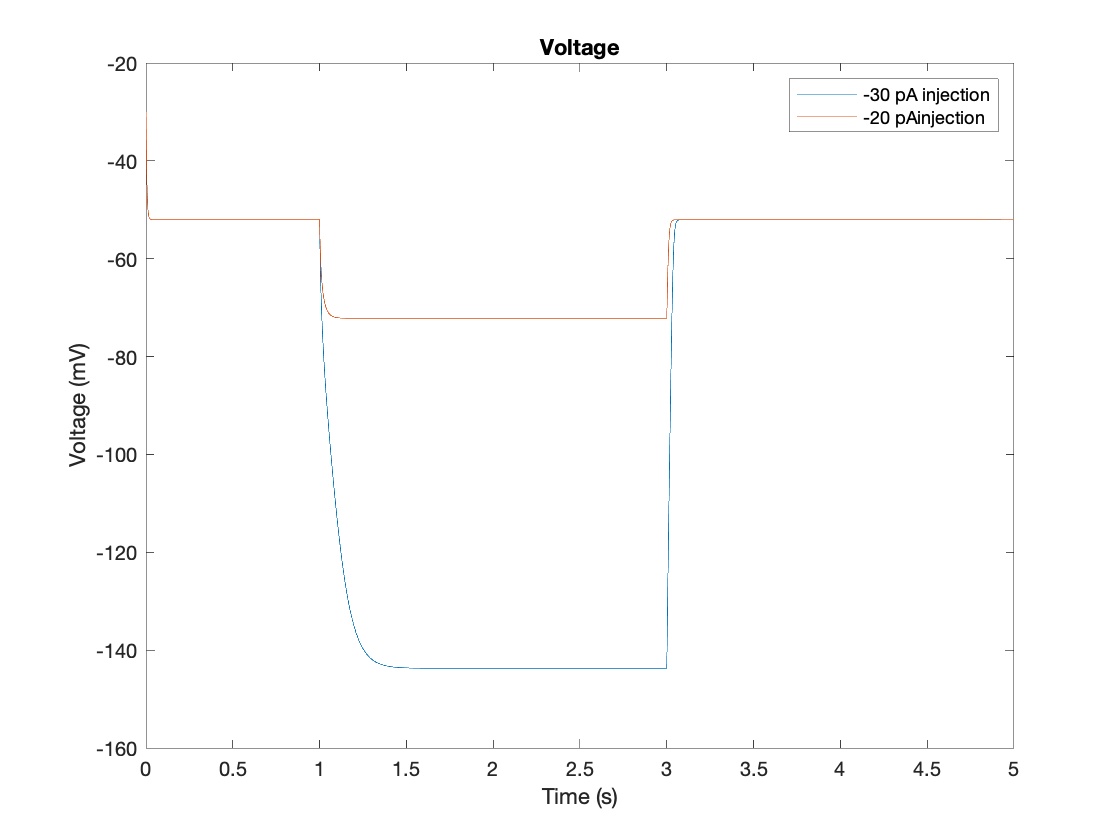

[tV, res] = calcV(tspan,-30);

V = res(:,5);
plot(tV, V)

hold on
[tV_20, res] = calcV(tspan,-20);

V_20 = res(:,5);
plot(tV_20, V_20)

title('Voltage')
xlabel('Time (s)')
ylabel('Voltage (mV)')
legend('-30 pA injection','-20 pA injection')
hold off

*Calcium current*

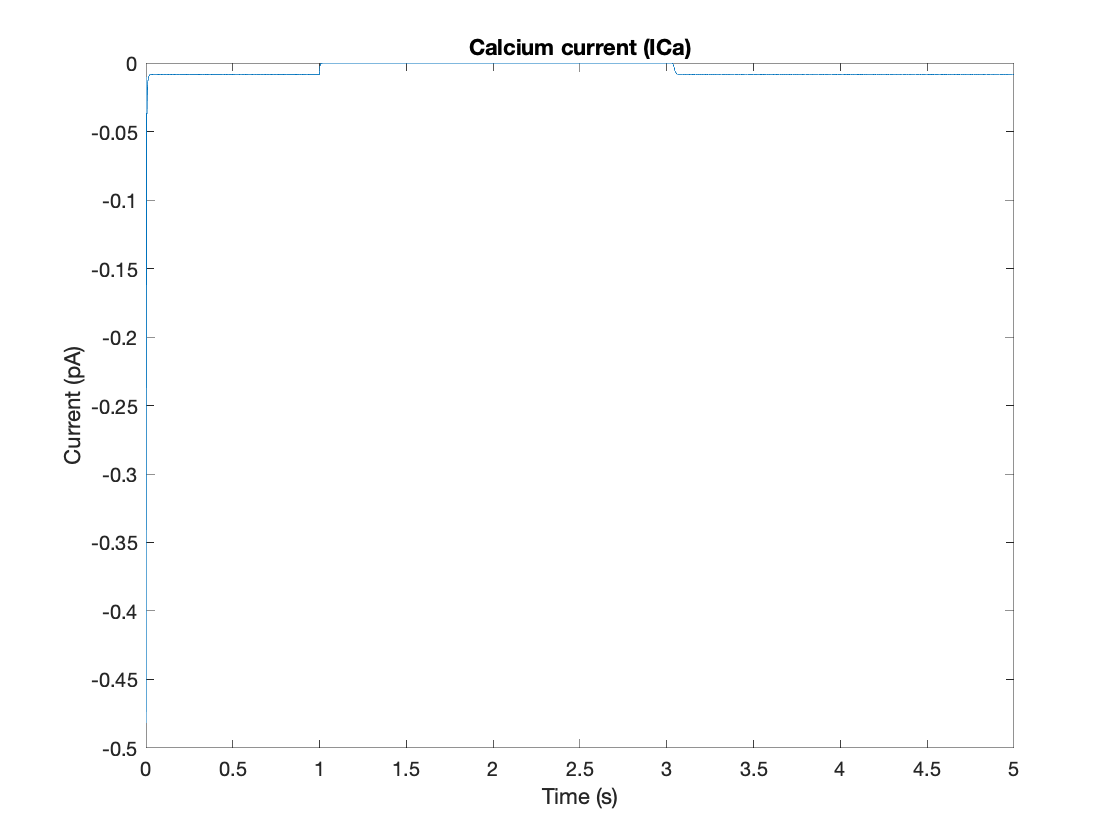

[t, ICa] = calcICa(tspan, tV, V, Cas);
plot(t, ICa)

title('Calcium current (ICa)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Calcium-dependent K current*

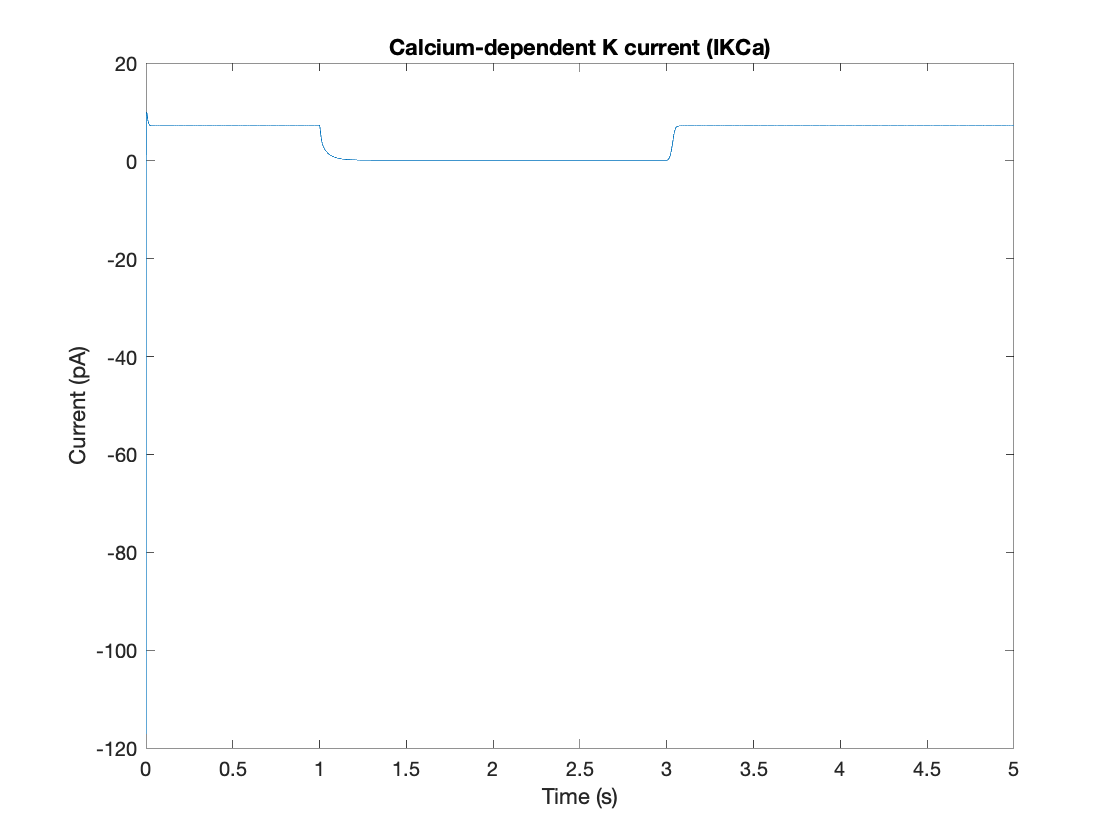

[t, IKCa] = calcIKCa(tspan, tV, V, Cas);
plot(t, IKCa)

title('Calcium-dependent K current (IKCa)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Delayed rectifying potassium current*

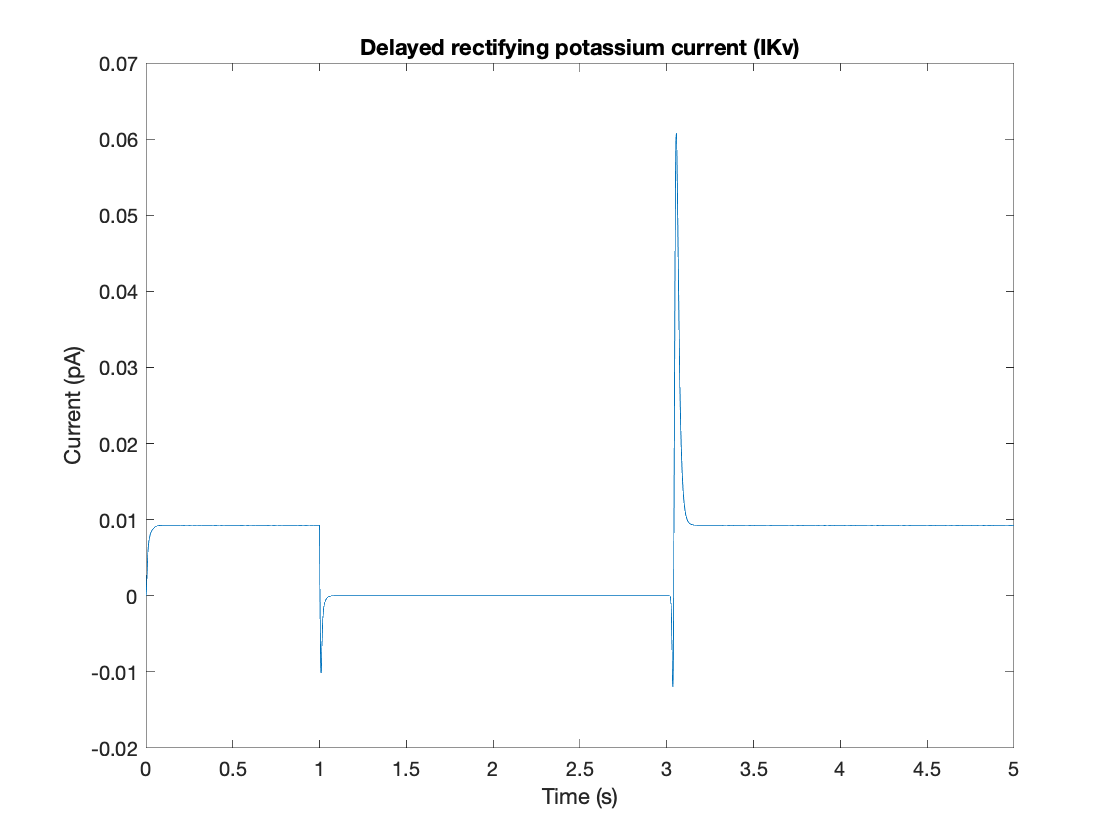

[t, IKv] = calcIKv(tspan, tV, V);
plot(t, IKv)

title('Delayed rectifying potassium current (IKv)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Hyperpolarization activated current*

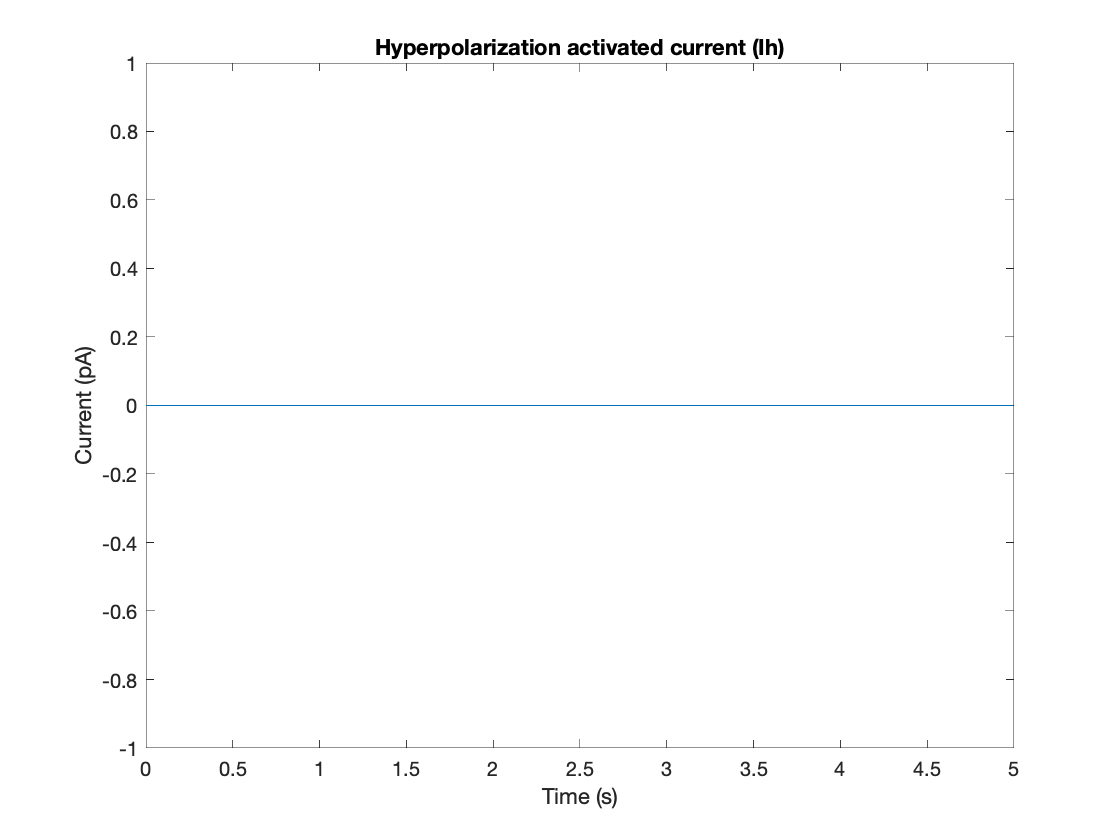

[t, Ih] = calcIh(tspan, tV, V);
plot(t, Ih)

title('Hyperpolarization activated current (Ih)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Leakage current*

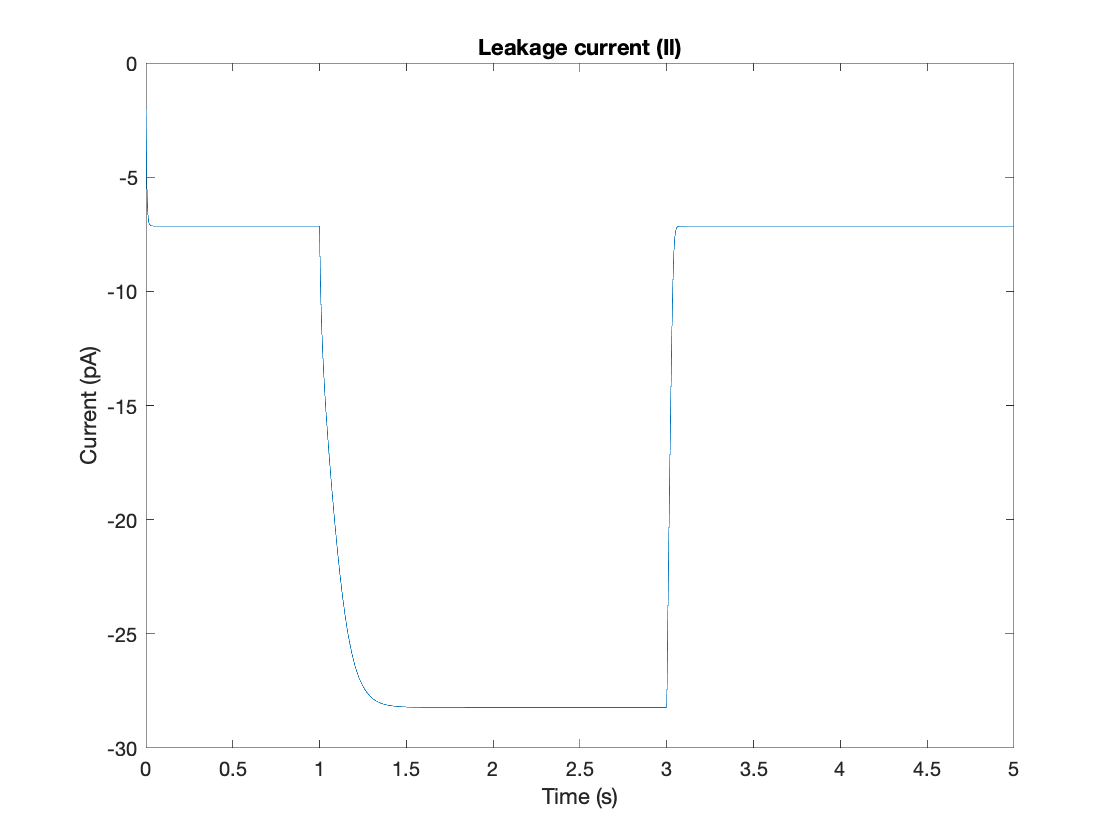

Il = calcIl(V);
plot(tV, Il)

title('Leakage current (Il)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Transient outward current (not needed to calculate voltage)*

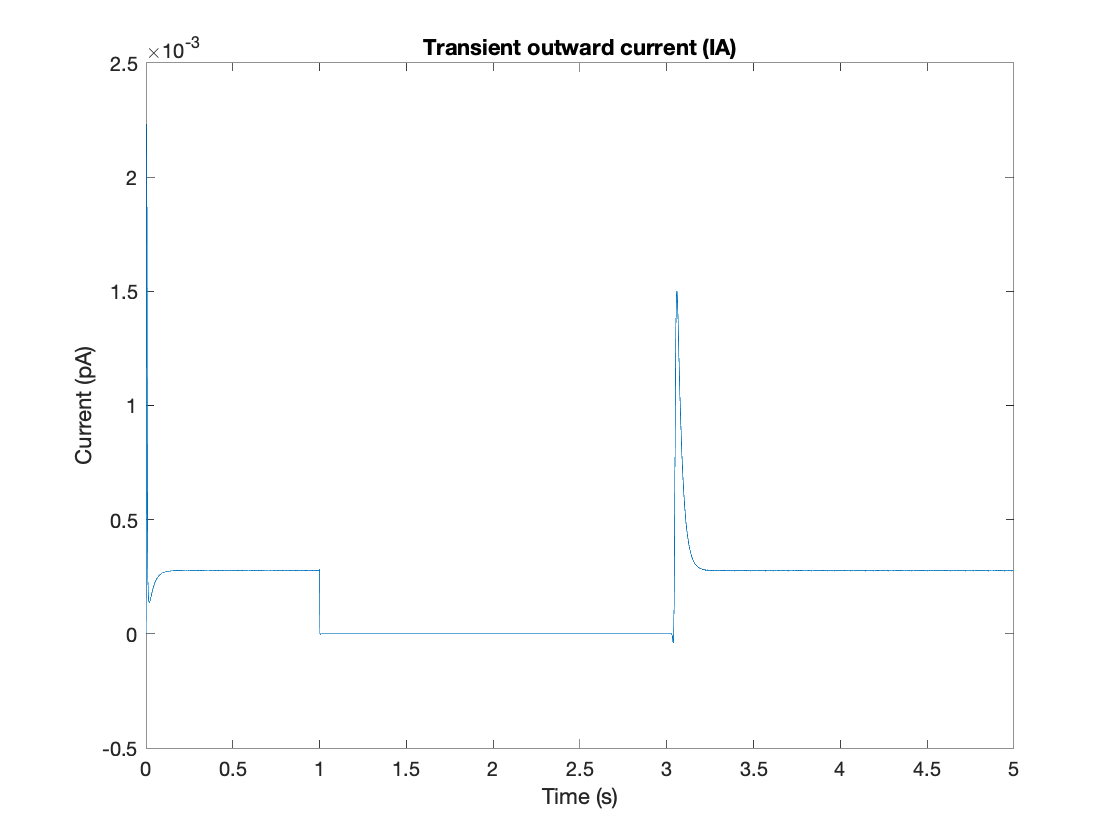

[t, IA] = calcIA(tspan, tV, V);
plot(t, IA)

title('Transient outward current (IA)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Total ionic current*

totalI = IKv+Ih+ICa+IKCa+Il+IA; % add injection current too

Matrix dimensions must agree.

plot(t, totalI)

title('Total ionic current')
xlabel('Time (s)')
ylabel('Current (pA)')